splitfolder = 'split1'

per = 20

optrank_1 = 2

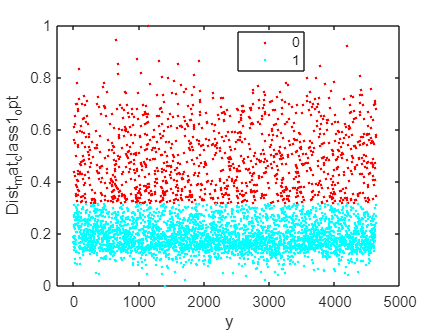

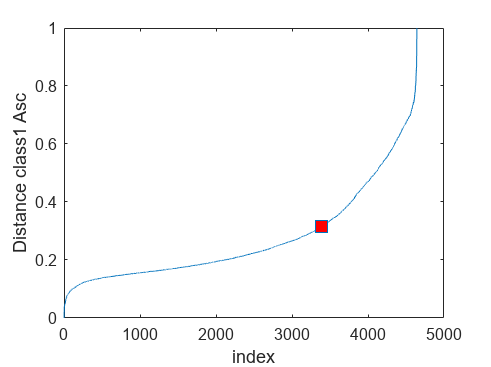

optrank_7 = 1

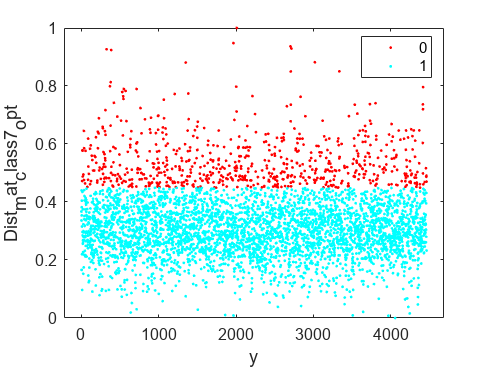

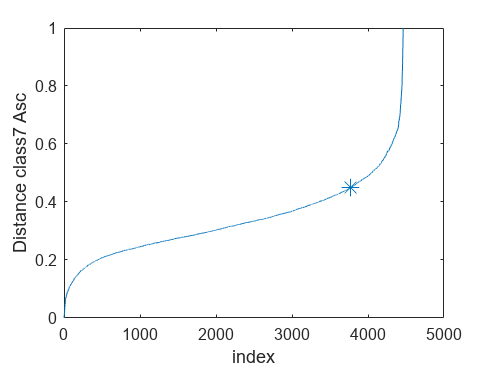

splitfolder = 'split2'

per = 20

optrank_1 = 3

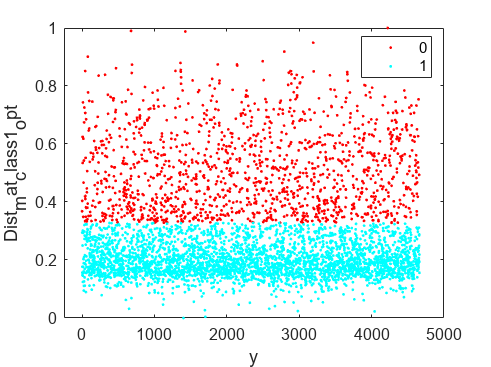

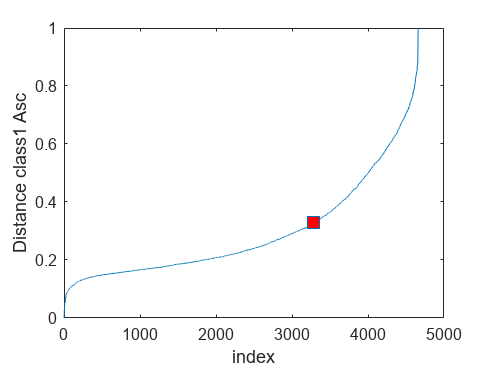

optrank_7 = 1

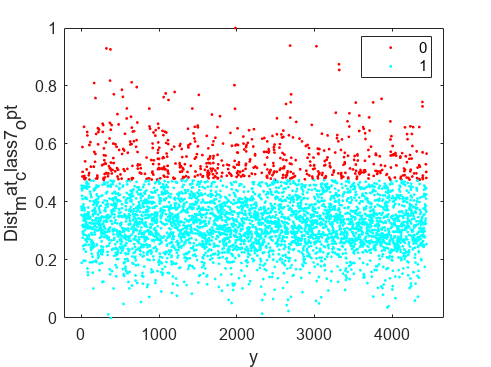

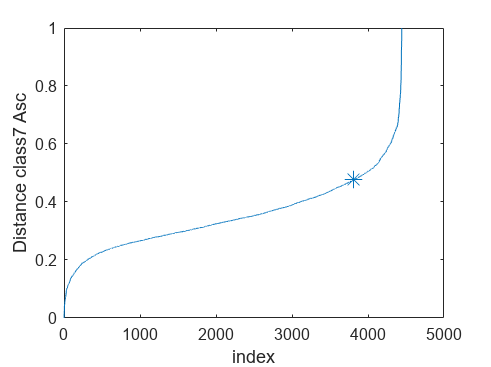

for j = [1,2]%[1,2,3]%,,7,8,9,10]
     splitfolder=strcat('split',num2str(j))
    M=importdata("C:\Users\shukl\Documents\GitHub\Mnist\split1\per20\mnist_misclass_per_20.csv",",",1);
    per =[0,5,10,15,25]%,10,5,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\Mnist\
        mkdir (splitfolder)
        cd (splitfolder)
        folder=strcat('per',num2str(percent));
        %         mkdir (folder)
        cd (folder)

        %my_file = 'mnist_17_train_set.csv';
        my_file = strcat('mnist_17_misclass_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);
        %cd (folder)

        class1=File(File(:,1)==1,2:785);
        T_class1=class1.';



        class7=File(File(:,1)==7,2:785);
        T_class7=class7.';


        folder_l1=strcat('ACE_17_dist_optrank_angle_l1pca_per',num2str(percent));
        mkdir (folder_l1)

        ranks=[1,2,3];%,6,7,8];

        error_class1 = nan(size(ranks));
        numclass1=length(T_class1);
        Dist_mat_class1_array_asc=nan(length(ranks),numclass1);
        threshold_rank_1=nan(size(ranks));
        elbow_indx_rank_1=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\Mnist\

            T_class1_temp=T_class1;
            Dist_mat_class1=[];


            BF_class1=l1pca_BF(T_class1,i,1,10,10,'');
            for k = 1 : numclass1
                A=T_class1(:,k);
                Dist_mat_class1(k)=norm((A-(BF_class1*BF_class1.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_class1,[],"all");
            max_val=max(Dist_mat_class1,[],"all");
            Dist_mat_class1= Dist_mat_class1-min_val;%]/[max_val-min_val]
            Dist_mat_class1=Dist_mat_class1 /(max_val-min_val);


            Dist_mat_class1_array_asc(i,:)=Dist_mat_class1;
            [Dist_mat_class1_asc,Indx_1]=sort(Dist_mat_class1,"ascend");


            [elbow_1_err_angle,elbow_indx_1]=knee_pt_angle((Dist_mat_class1_asc));

            error_class1(i)=elbow_1_err_angle;
            threshold_rank_1(i)=Dist_mat_class1_asc(elbow_indx_1);
            elbow_indx_rank_1(i)=elbow_indx_1;

        end

        [~,optrank_1]= max(error_class1)

        Dist_mat_class1_opt=Dist_mat_class1_array_asc(optrank_1,:);
        threshold_dist_1= threshold_rank_1(optrank_1);
        elbow_indx_1_opt=elbow_indx_rank_1(optrank_1);

        ind_O_1=find(Dist_mat_class1_opt>threshold_dist_1);
        ind_I_1=find(Dist_mat_class1_opt<=threshold_dist_1);


        cluster_1=zeros(size(Dist_mat_class1_opt));
        cluster_1(ind_I_1)=1;
        % figure
        % y= 1:1:length(class1);
        % numGroups = length(unique(cluster_1));
        % gscatter(y,Dist_mat_class1_opt,cluster_1,hsv(numGroups))
        % 
        % figure
        % plot(sort(Dist_mat_class1_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_1_opt),'MarkerFaceColor','red','MarkerSize',10 )
        % xlabel("index")
        % ylabel("Distance class1 Asc")
        % ind_O_1;


        T_class1_temp(:,ind_O_1)=[];
        length(T_class1_temp);


        Final_class1=T_class1_temp';
        c1=ones(size(Final_class1,1),1);
        Final_class1=[c1 Final_class1];


        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        error_class7 = nan(size(ranks));
        numclass7=length(T_class7);
        Dist_mat_class7_array_asc=nan(length(ranks),numclass7);
        threshold_rank_7=nan(size(ranks));
        elbow_indx_rank_7=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\Mnist\

            T_class7_temp=T_class7;
            Dist_mat_class7=[];


            BF_class7=l1pca_BF(T_class7,i,1,10,10,'');
            for k = 1 : numclass7
                A=T_class7(:,k);
                Dist_mat_class7(k)=norm((A-(BF_class7*BF_class7.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_class7,[],"all");
            max_val=max(Dist_mat_class7,[],"all");
            Dist_mat_class7= Dist_mat_class7-min_val;%]/[max_val-min_val]
            Dist_mat_class7=Dist_mat_class7 /(max_val-min_val);


            Dist_mat_class7_array_asc(i,:)=Dist_mat_class7;
            [Dist_mat_class7_asc,Indx_7]=sort(Dist_mat_class7,"ascend");


            [elbow_7_err_angle,elbow_indx_7]=knee_pt_angle(Dist_mat_class7_asc);

            error_class7(i)=elbow_7_err_angle;
            threshold_rank_7(i)=Dist_mat_class7_asc(elbow_indx_7);
            elbow_indx_rank_7(i)=elbow_indx_7;

        end

        [~,optrank_7]= max(error_class7)

        Dist_mat_class7_opt=Dist_mat_class7_array_asc(optrank_7,:);
        threshold_dist_7= threshold_rank_7(optrank_7);
        elbow_indx_7_opt=elbow_indx_rank_7(optrank_7);

        ind_O_7=find(Dist_mat_class7_opt>threshold_dist_7);
        ind_I_7=find(Dist_mat_class7_opt<=threshold_dist_7);


        cluster_7=zeros(size(Dist_mat_class7_opt));
        cluster_7(ind_I_7)=1;
        % figure
        % y= 1:1:length(class7);
        % numGroups = length(unique(cluster_7));
        % gscatter(y,Dist_mat_class7_opt,cluster_7,hsv(numGroups))
        % 
        % figure
        % plot(sort(Dist_mat_class7_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_7_opt),'MarkerFaceColor','red','MarkerSize',10 )
        % xlabel("index")
        % ylabel("Distance class7 Asc")
        % ind_O_7;


        T_class7_temp(:,ind_O_7)=[];
        length(T_class7_temp);

        Final_class7=T_class7_temp';

        c2=7*ones(size(Final_class7,1),1);
        Final_class7=[c2 Final_class7];


        cd C:\Users\shukl\Documents\GitHub\Mnist\
        cd (splitfolder)
        cd (folder)

        cd (folder_l1)

        L1pca_file=(horzcat(Final_class1.',Final_class7.')).';

        L1pca_file = array2table(L1pca_file);
        L1pca_file.Properties.VariableNames(1:785)=  M.colheaders;
        filel1pca=strcat('mnist_17_misclass_per',num2str(percent),'_ACE_l1pca.csv');
        writetable(L1pca_file,filel1pca);
    end
end